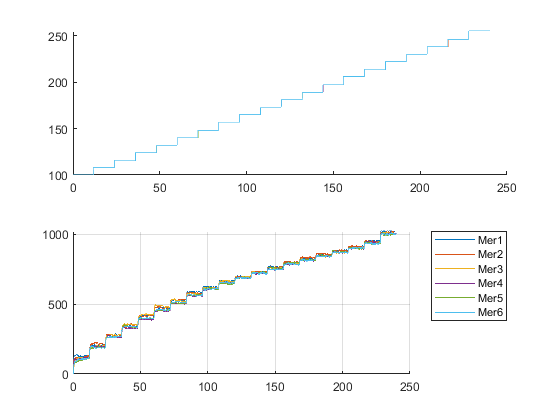

data = zeros(13541,3,6);
for i=1:12
    fileName = ['./dataRepo/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    data(:,:,i) = dt(2:13542,:);
end

figure;
for i=1:6
    subplot(2,1,1);    
    name = ['Mer',num2str(i)];
    hold on;
    plot(data(:,1,i),data(:,2,i), 'DisplayName',name);
    hold off;
    subplot(2,1,2);
    hold on;
    plot(data(:,1,i),data(:,3,i),'DisplayName',name)
    hold off;
end
legend('Location',"bestoutside");
grid on;

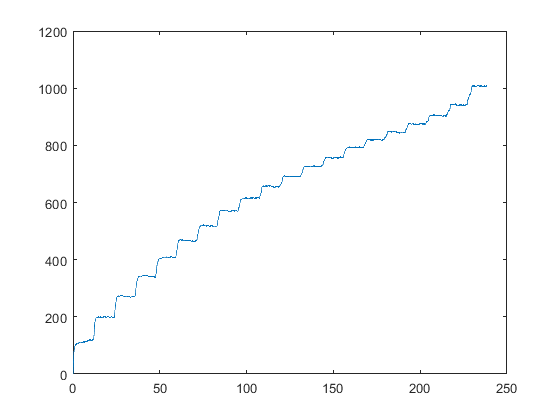

dataSimple = zeros(6,13541);
for i=1:6    
    dataSimple(i,:) = data(:,3,i)';
end
dataMean = mean(dataSimple);
dataMean = dataMean';
figure;
plot(data(:,1,1),dataMean(:),'DisplayName',name)

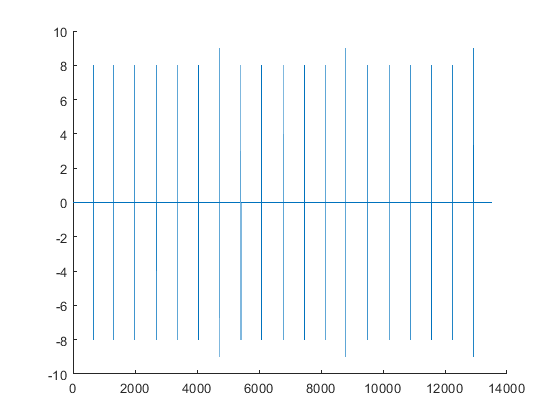

timeData = data(:,1,1);
inputData = data(:,2,1);
outputData = data(:,3,1);

diffVal = diff(inputData);
diffVal2 = diff(diffVal);
figure;
hold on;
%plot(diffVal)
plot(diffVal2)
hold off;

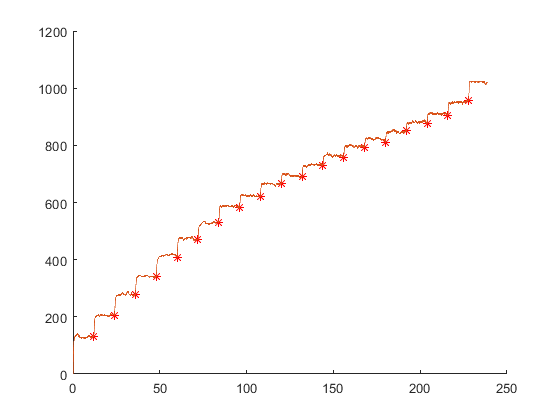


ids = find(or(diffVal > 4,diffVal < -4));
ln = size(ids,1);
finalData = zeros(ln,2);
for i=1:ln    
    finalData(i,1) = timeData(ids(i));
    finalData(i,2) = outputData(ids(i,1));
end

figure;
hold on;
plot(finalData(:,1),finalData(:,2),'*r');
plot(timeData,outputData);
hold off;

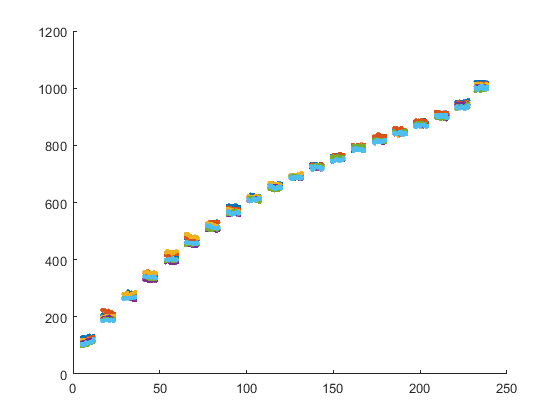

n = 6;
m = 20;
w = 400;
dataStore = zeros(m*w,n+1);
for i=1:n    
    diffVal = diff(data(:,2,i));
    ids = find(or(diffVal > 0,diffVal < 0));    
    ln = size(ids,1);
    if(ln == m-1)
        id = [ids;13541];
        for j=1:m
            if i == 1
                dataStore(1+w*(j-1):w*j,1) = data(id(j)-(w-1):id(j),1,i);
            end
            dataStore(1+w*(j-1):w*j,i+1) =  data(id(j)-(w-1):id(j),3,i);
        end   
    end
end

figure;
hold on;
for i=1:n
    plot(dataStore(:,1), dataStore(:,1+i),'.');
end
hold off;

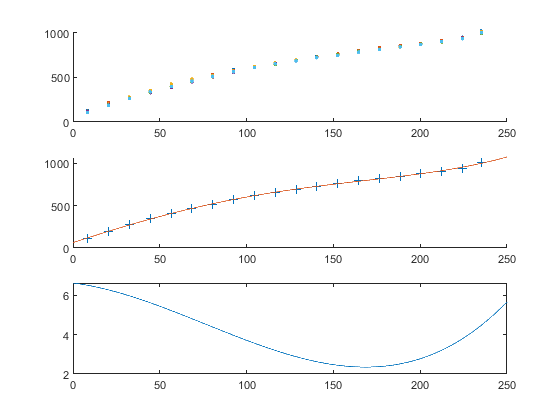


dataMean = zeros(m,n+1);
for i=1:n+1
    for j=1:m     
        if i == 1            
            dataToMean = dataStore(1+w*(j-1):w*j-1,i);
            dataMean(j,i) = mean(dataToMean);
        else
            dataToMean = dataStore(1+w*(j-1):w*j-1,i);
            dataMean(j,i) = mean(dataToMean);
        end        
    end
end
dataFullMean = zeros(m,2);
dataFullMean(:,1) = dataMean(:,1);
dataFullMean(:,2) = mean(dataMean(:,2:end)');

[p, S] = polyfit(dataFullMean(:,1),dataFullMean(:,2),4);
[q,d] = polyder(p);
x1 = linspace(0,250,1000);
[y1,delta] = polyval(p,x1,S);
y2 = polyval(q/d,x1);
figure;
subplot(3,1,1);
hold on;
for i=1:n
    plot(dataMean(:,1), dataMean(:,1+i),'.');
end
hold off;
subplot(3,1,2);
hold on;
plot(dataFullMean(:,1),dataFullMean(:,2),'+','DisplayName','Body')
plot(x1,y1,'DisplayName','Polyfit 4');
hold off;

subplot(3,1,3)
plot(x1,y2,'DisplayName','Polyder');